# Power Amplifier Characterization

## Select Data Source

dataSource = "From file";

## Generate Test Signals

To generate a test signal, specify the type of test signal as "`OFDM`" or "`Tones`". Specifying the `testSignal` as "`OFDM`" uses a 5G-like OFDM waveform with 64-QAM modulated signals for each subcarrier. "`Tones`" uses two tones at 1.8 MHz and 2.6 MHz, to test the intermodulation caused by the PA. 

The example will use an oversampling factor of 7 to run the grid search up to an expected seventh-order nonlinearity, and normalize the waveform amplitude. 

testSignal = "OFDM";
switch testSignal
  case "OFDM"
    bw = 15e6;
    [txWaveform,sampleRate,numFrames] = helperPACharGenerateOFDM(bw);
  case "Tones"
    bw = 3e6;
    [txWaveform,sampleRate,numFrames] = helperPACharGenerateTones();
end
txWaveform = txWaveform/max(abs(txWaveform));   % Normalize the waveform

if strcmp(dataSource, "Hardware")
  VST = helperVSTDriver('VST_01');

Set the expected gain values of the DUT and the attenuator. Since PA output is connected to a 30 dB attenuator, set VSA external attenuation to 30. Set the expected gain of the DUT to 29 dB and gain accuracy to 1 dB. Set the acquisition time to a value that will result in about 40k samples. Set the target input power to 8 dBm. You can increase this value to drive the PA more into the non-linear region. 

  VST.DUTExpectedGain     = 29;     % dB
  VST.ExternalAttenuation = 30;     % dB
  VST.AcquisitionTime     = 0.9e-3*(53.76e6/sampleRate); % seconds
  VST.DUTTargetInputPower =8;  % dBm
  VST.CenterFrequency     = 3.7e9   % Hz

Download the test waveform to the VSG. Measure PA output.

  writeWaveform(VST,txWaveform,sampleRate,testSignal)
  results = runPAMeasurements(VST);
  release(VST)
else
  % Load the prerecorded results from VST
  switch testSignal
    case "OFDM"
      dataFileName = sprintf("helperPACharSavedData%dMHz",bw/1e6);
    case "Tones"
      dataFileName = "helperPACharSavedDataTones";
  end
  load(dataFileName,"results","sampleRate","overSamplingRate","testSignal","numFrames")
end

Map results into local variables.

referencePower = results.ReferencePower;
measuredAMToAM = results.MeasuredAMToAM;
paInput = results.InputWaveform;
paOutput = results.OutputWaveform;
linearGaindB = results.LinearGain;

Plot the spectrum of the test signal using the [spectrumAnalyzer](docid:dsp_ref#mw_d312d509-f3fe-49bd-9fe1-dd35c86ae976) function.

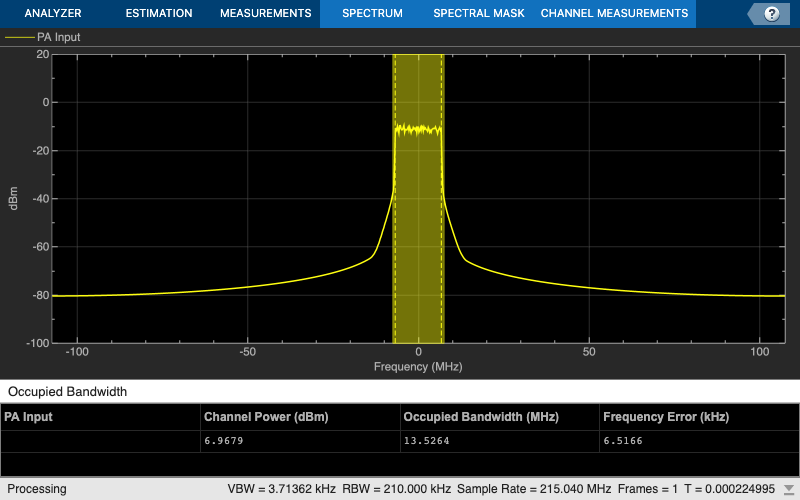

saInput = helperPACharPlotInput(paInput, sampleRate, testSignal, bw);

Plot the AM/AM characteristics of the PA.

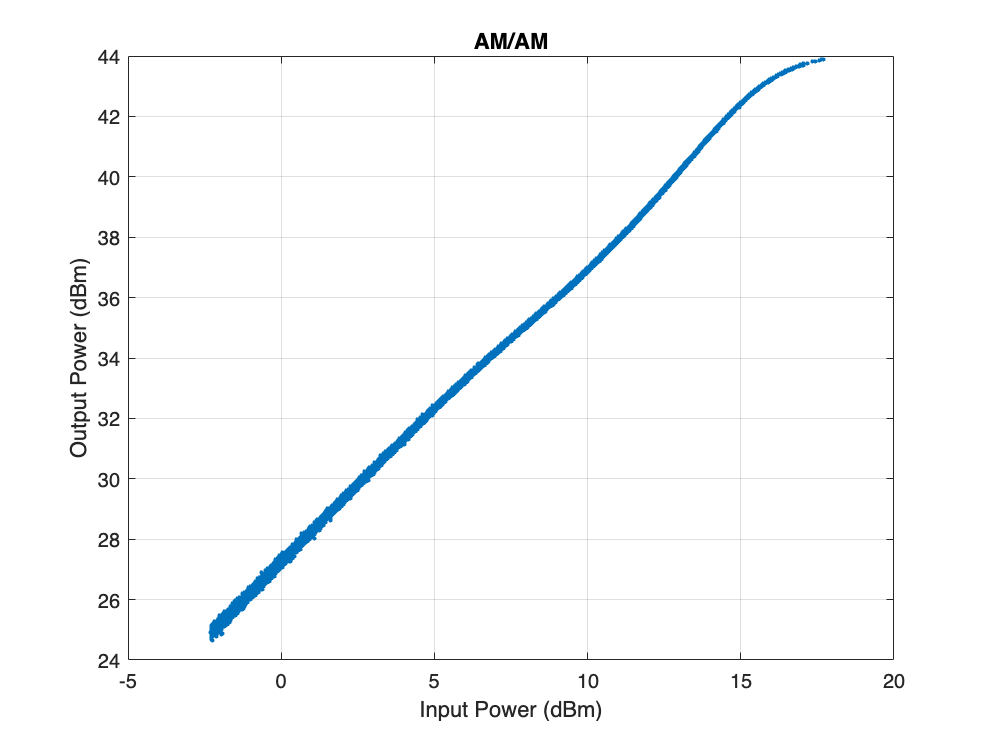

helperPACharPlotSpecAnAMAM(referencePower, measuredAMToAM);

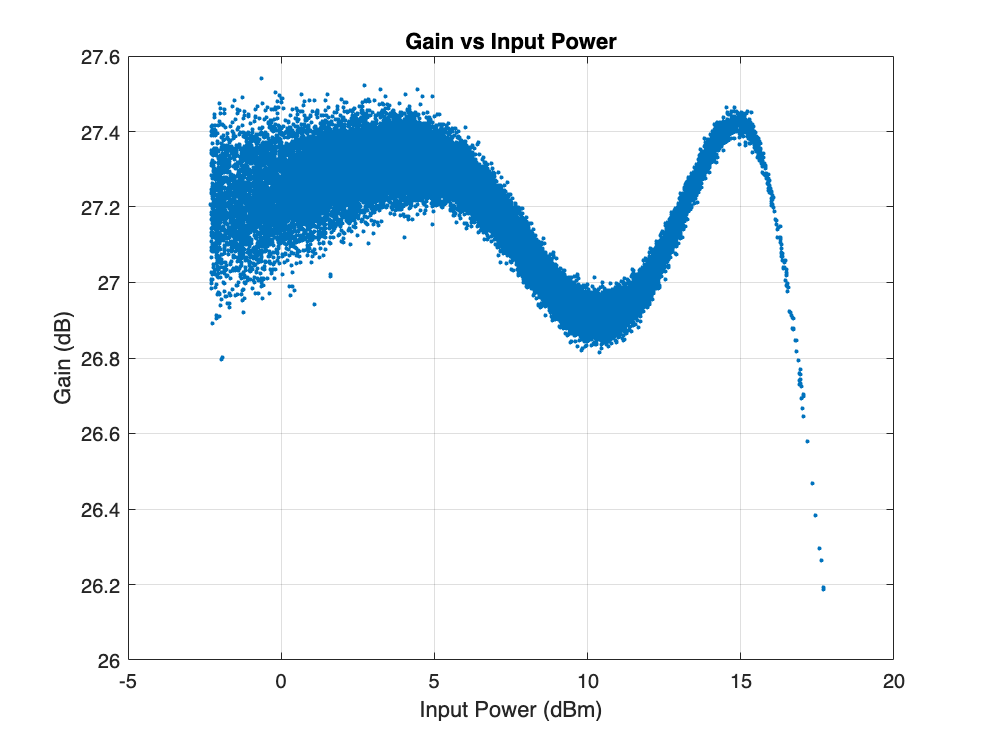

helperPACharPlotSpecAnGain(referencePower, measuredAMToAM)

The PA is mostly linear of the input power range -1 to 17 dBm, with only about 1dB variation over that range. The width of the gain curve is due to the memory effects of the PA. 

## PA Characterization

Use the measured PA input and output data to model the PA. Then, you can use this model to simulate a system that contains this PA and fine tune the parameters. This example considers three models: memoryless nonlinearity, memory polynomial and memory polynomial with cross terms. 

### Memoryless Nonlinearity Model

Memoryless nonlinear impairments distort the input signal amplitude and phase. The amplitude distortion is amplitude-to-amplitude modulation (AM/AM) and the phase distortion is amplitude-to-phase modulation (AM/PM). The [comm.MemorylessNonlinearity](docid:comm_ref#bsnfpwe_2) System object and [Memoryless Nonlinearity](docid:comm_ref#fp687424) block implements several such distortions. Use the PA input and output data to create a lookup table to use with this object or block.

To characterize the AM/AM transfer function, calculate the average output power for a range of input power values. Measurements are in volts over an overall 100 ohm impedance, split between the transmitter and receiver. Convert the measured baseband samples to power values in dBm. The +30 dB term is for dBW to dBm conversion and the -20 dB term is for the 100 ohm impedance.

paInputdBm  = mag2db(abs(paInput)) + 30 - 20;
paOutputdBm  = mag2db(abs(paOutput)) + 30 - 20;

Partition the input power values into bins. The `edges` variable contains the bin edges, and the `idx` variable contains the index of the bin values for each input power value. 

[N,edges,idx] = histcounts(paInputdBm, 'BinWidth', 0.5);

For each bin, calculate the midpoint of the bin, average output power and average phase shift. Do not include any input power value that is less than 20 dB below the maximum input power. Store the results in a three-column matrix where the first column is the input power in dBm, second column is the output power in dBm and last column is the phase shift. 

minInPowerdBm = max(paInputdBm) - 20;
minIdx = find(edges < minInPowerdBm, 1, 'last');
tableLen = length(edges)-minIdx-1;
inOutTable = zeros(tableLen,2);
for p = minIdx+1:length(edges)-1
  inOutTable(p-minIdx,1) = mean(paInputdBm(idx == p));   % Average input power for current bin
  inOutTable(p-minIdx,2) = mean(paOutputdBm(idx == p));  % Average output power for current bin
  inOutTable(p-minIdx,3) = mean(angle(paOutput(idx == p)./paInput(idx == p)));  % Average phase shift for current bin
end

Use the table in the comm.MemorylessNonlinearity System object to model the PA. Compare the estimated output with the actual output.

pa = comm.MemorylessNonlinearity('Method','Lookup table','Table',inOutTable,'ReferenceImpedance',100)

pa =   comm.MemorylessNonlinearity with properties:

                Method: 'Lookup table'
                 Table: [40×3 double]
    ReferenceImpedance: 100


paOutputFitMemless = pa(paInput);
err = abs(paOutput - paOutputFitMemless)./abs(paOutput);
rmsErrorMemless = rms(err)*100;
disp(['Percent RMS error in time domain is ' num2str(rmsErrorMemless) '%'])

Percent RMS error in time domain is 9.9109%


To visualize both the measured output signal and the fitted output signal, plot the actual and fitted time-domain output voltages.

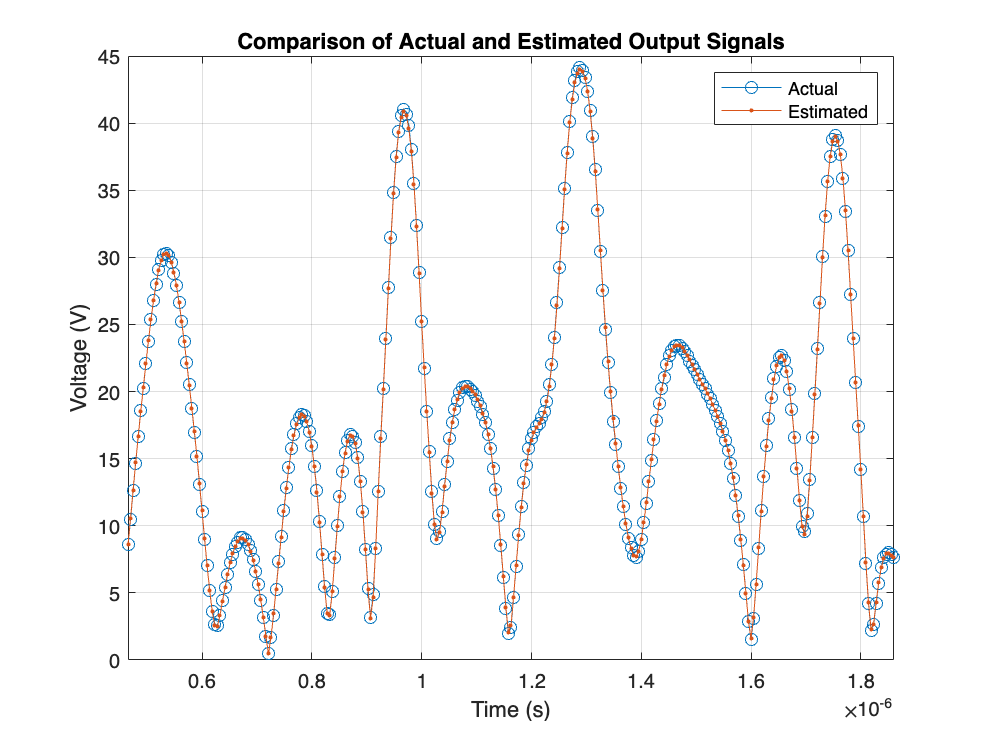

helperPACharPlotTime(paOutput, paOutputFitMemless, sampleRate)

Plot the magnitude of the gain.

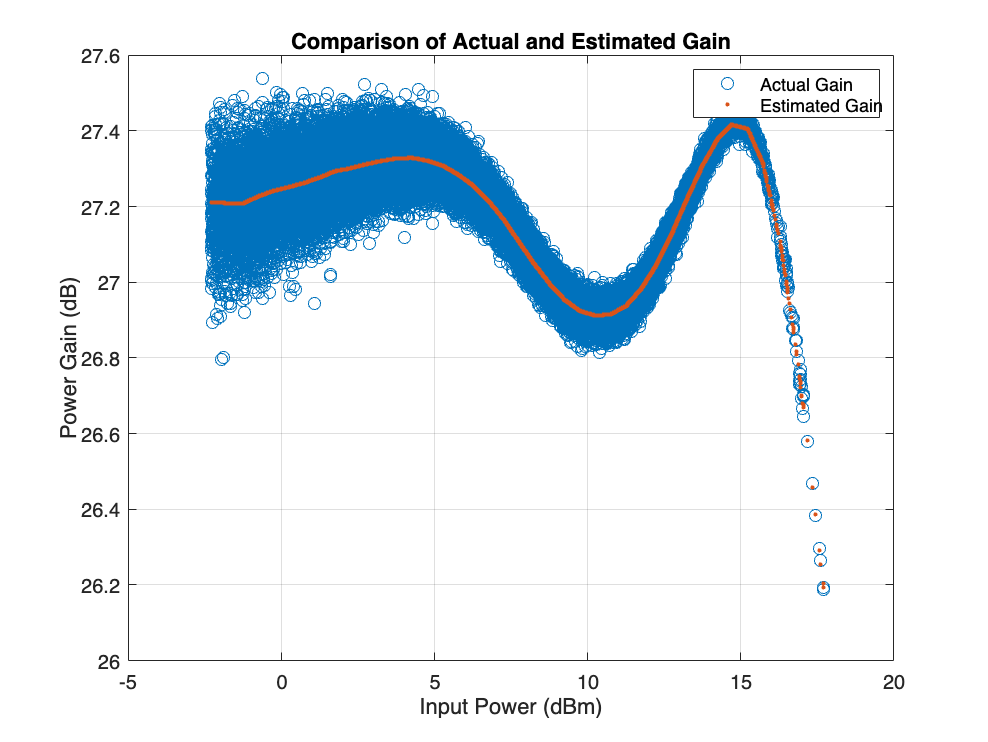

helperPACharPlotGain(paInput, paOutput, paOutputFitMemless)

### Memory Polynomial Model

The memory polynomial model includes the memory effects of the PA in addition to the nonlinear gain. Use the multipurpose helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) to determine the complex coefficients of a memory polynomial model for the amplifier characteristics. Set the model type to `'Memory Polynomial'`. 

modType = 'ctMemPoly';

Perform a grid search as shown in Appendix Grid Search for Memory Length and Polynomial Order. Based on this grid search results, the best fit is obtained when memory length and polynomial degree values are as follows:

memLen = 5;
degLen = 5;

Perform the fit and RMS error calculation for these values. Only half of the data is used to compute the fitting coefficients, as the whole data set will be used to compute the relative error. The helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) calculates the coefficients of the model. 

numDataPts = length(paInput);
halfDataPts = round(numDataPts/2);

The helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) is editable for custom modifications, and to return the desired matrix. The PA model has some zero valued coefficients, which results in a rank deficient matrix.

fitCoefMatMem = helperPACharMemPolyModel('coefficientFinder',             ...
  paInput(1:halfDataPts),paOutput(1:halfDataPts),memLen,degLen,modType);

disp(abs(fitCoefMatMem))

   22.7368   10.0707         0    2.4739    6.0942    3.9367   32.5854         0   22.2416         0    9.3198   32.9359   17.6986         0   11.3946   11.2433   11.2805   10.7724         0    6.3523    3.6028
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   14.2225         0         0
    4.1198         0   16.2911         0         0         0         0         0         0    2.6917         0   24.3006         0         0         0         0   15.1181    7.2923         0   11.8396    4.9200
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    2.1041    8.6058    9.1952    1.8564         0    2.6130   18.1861         0    6.4398         0    6.2332    4.8877    8.1512         0    5.1107    5.

To validate the fitting, use the helper function to compute percent RMS error with respect to the measured signal.

rmsErrorTimeMem = helperPACharMemPolyModel('errorMeasure', ...
  paInput, paOutput, fitCoefMatMem, modType);
disp(['Percent RMS error in time domain is ' num2str(rmsErrorTimeMem) '%'])

Percent RMS error in time domain is 4.202%


To visualize both the measured output signal and the fitted output signal, plot the actual and fitted time-domain output voltages.

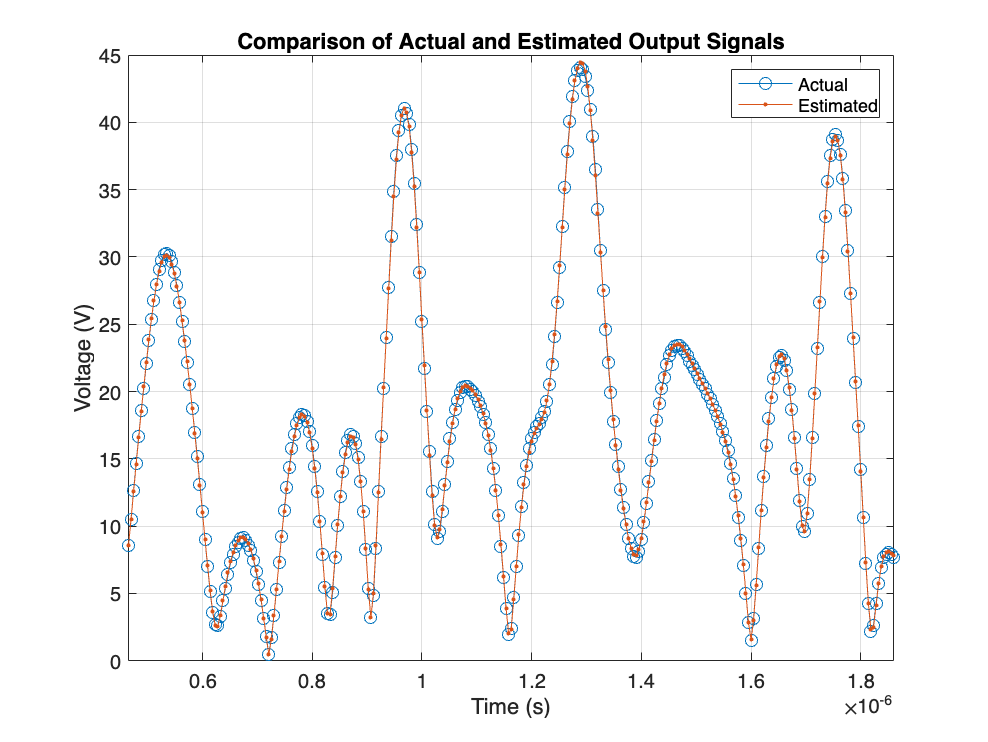

paOutputFitMem = helperPACharMemPolyModel('signalGenerator', ...
  paInput, fitCoefMatMem, modType);
helperPACharPlotTime(paOutput, paOutputFitMem, sampleRate)

Plot the magnitude of the gain.

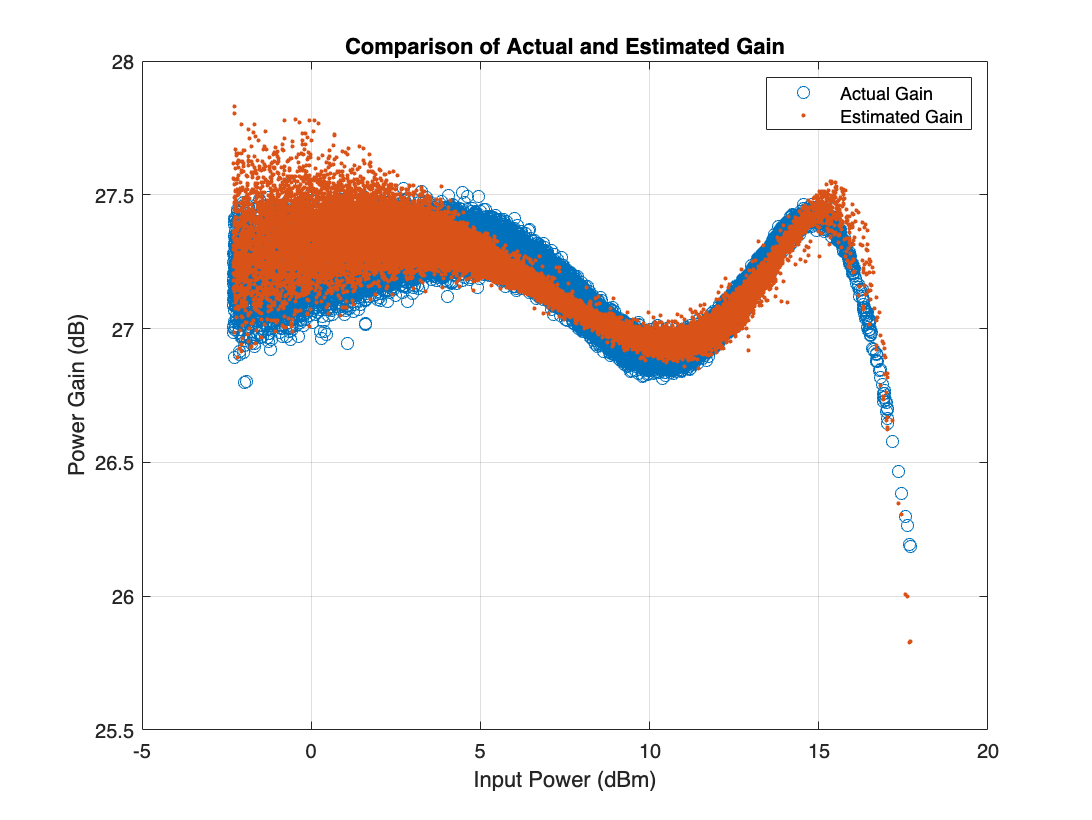

helperPACharPlotGain(paInput, paOutput, paOutputFitMem)

The percent RMS estimation error in time domain for the memoryless nonlinearity model, which is between 9% and 13%, is about 3 to 4 times more than the error for the memory polynomial model is, which is between 2% and 6%, for the OFDM signals with different bandwidths. 

Check the estimation error in frequency domain by plotting the spectrum of the actual PA output together with the spectrum of the estimated PA output for all three models. The memoryless nonlinearity table lookup model is not able to simulate the spectral growth seen in the measured PA output. For this PA, memory polynomial model provides a good approximation of the PA characteristics.

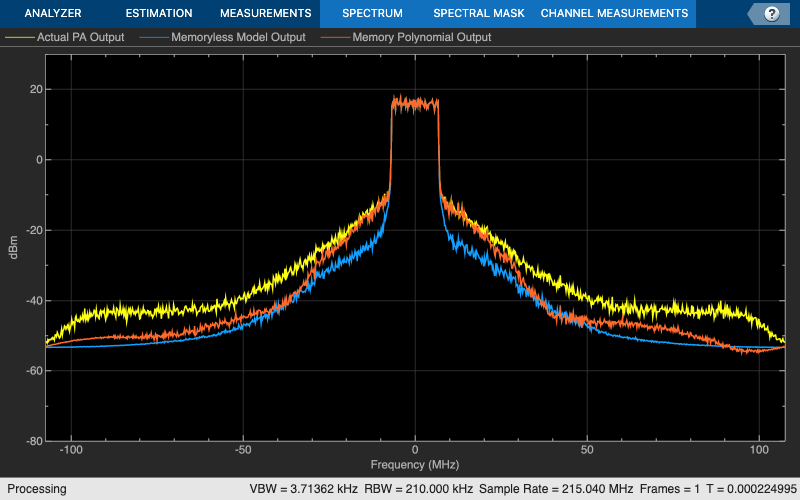

sa = helperPACharPlotSpectrum(...
  [paOutput paOutputFitMemless paOutputFitMem],...
  {'Actual PA Output','Memoryless Model Output', ...
  'Memory Polynomial Output'},...
  sampleRate,testSignal);

The helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) can also use the memory polynomial with cross terms model, which includes the leading and lagging memory cross terms in addition to the memory effects of the PA and the nonlinear gain. Set the model type to `'Cross-Term Memory'` to explore this model.

For further exploration, try different memory length and polynomial degree combinations. Modify the oversampling factor and explore its effect on the PA model performance. Modify the helper function [helperPACharMemPolyModel](matlab:openExample('shared_comm_rf/PACharacterizationwithVSTExample','supportingFile', 'helperPACharMemPolyModel.m')) to try different PA models.

frameSize = floor(length(paInput)/numFrames);
paIn.signals.values = double(reshape(paInput(1:frameSize*numFrames,1),numFrames,frameSize));
paIn.signals.dimensions = frameSize;
paIn.time = [];
save('PAcoefficientsAndInput.mat','modType','fitCoefMatMem','memLen','degLen','paIn','linearGaindB')

## Appendix: Grid Search for Memory Length and Polynomial Order

Uncomment following lines to perform the grid search when the cost function is the percent RMS error in time. First choose the model type.

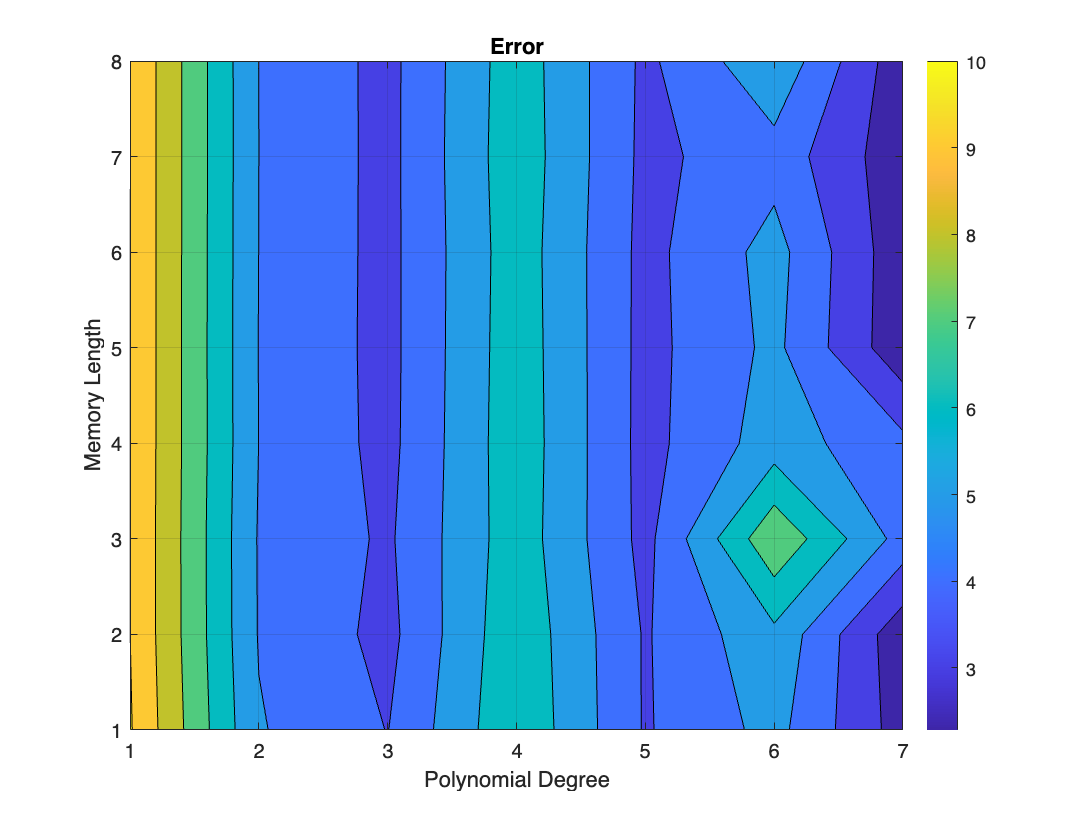

rmsErrorTime =    10.0854    5.0796    3.9760    6.8604    3.9042    5.3276    2.5319
   10.0073    4.9408    3.7095    6.7581    3.9055    5.7586    2.3140
   10.0049    4.9214    3.8465    6.5827    3.6884    7.8228    4.5919
   10.0086    4.9917    3.7145    6.6413    3.6579    5.4994    4.2511
   10.0117    4.9765    3.6965    6.6056    3.6733    5.2392    2.2842
   10.0114    4.9924    3.7020    6.5690    3.6864    5.3693    2.3024
   10.0162    5.0013    3.7032    6.6482    3.7420    4.6151    2.3244
   10.0171    4.9981    3.7018    6.5948    3.7792    5.8153    2.3231


modType = 'memPoly';
rmsErrorTime = helperPACharGridSearchTime(paInput,paOutput,modType,overSamplingRate)

Repeat the search when the cost function is the percent RMS error in frequency.

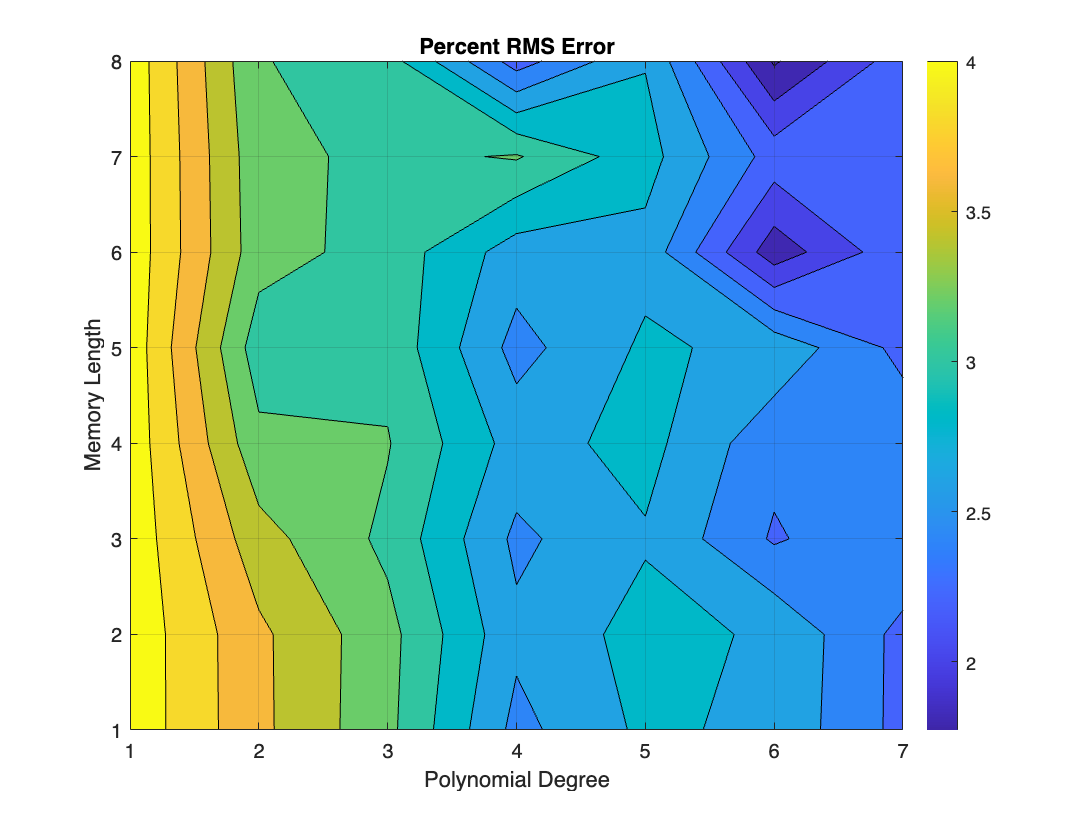

rmsErrorFreq =     4.1360    3.6467    3.2547    2.5379    2.8423    2.7481    2.3359
    4.1359    3.6420    3.2651    2.6478    2.8732    2.7670    2.3369
    4.1357    3.4779    3.1517    2.5559    2.7790    2.3758    2.5844
    4.1354    3.2546    3.2126    2.7151    2.8682    2.4619    2.5363
    4.1355    3.0878    3.1397    2.5298    2.8343    2.7405    2.3370
    4.1356    3.2819    3.1218    2.6992    2.7317    1.8837    2.3429
    4.1357    3.2677    3.1428    3.2188    2.8791    2.3150    2.3392
    4.1358    3.2133    3.0875    2.3039    2.7883    1.7732    2.3173


rmsErrorFreq = helperPACharGridSearchFrequency(paInput,paOutput,modType,overSamplingRate)